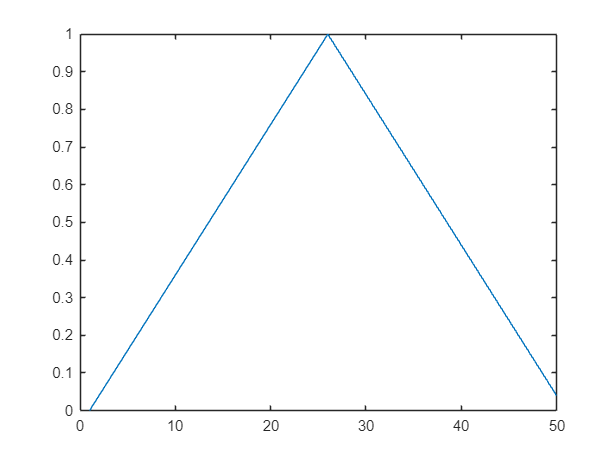

clc;
clear;
fs=125e6;
f=2.5e6;
nsamp=fs/f;
[L,P]=rat(nsamp);
nump=P*nsamp;
if mod(L,P)~=0
    nsamp=floor(nsamp)+1;
end


c1=[];
c2=[];
if mod(nsamp,2)==0
   
    c1=linspace(0,1,nsamp/2+1);
    c2=linspace(1,0,nsamp/2+1);
    c2=c2(2:end-1);
else
    c1=linspace(0,1,floor(nsamp/2)+1);
    c2=linspace(1,0,floor(nsamp/2)+2);
    c2=c2(2:end-1);
end
cc=[c1 c2];
plot(cc);

 x=lcm(nump,512);
 multi=x/nump*P;  %一共需要多少个周期
 xx=repmat(cc,1,multi)

 % 计算需要抽取多少个点

plot(xx);

% t=(0:x-1)/fs;
% 
% % t = linspace(0, 4*pi, 10);  % 6π对应3个完整周期
% y = sawtooth(t, 0.5);       % 0.5表示对称三角波
% plot(y);